% PURPOSE:
%   Uses IMU data to epoch the EEG and EMG data. Each epoch is some number 
%   of data points either side of the heel strike from the dominant leg
%   (which has the EMG electrodes attached).
%   Often, sections require some user input (described by ALL CAPS) before
%   clicking 'Run Section'.
% INPUT: 
%   C_trials_p, the processed EMG and EEG data
%   C_trials, the raw Cyton IMU data and the time vector
% OUTPUT: 
%   EMGepochs_TX, A 2D matrix of EMG epochs for each dominant-leg heel 
%       strike during trial X.
%   EEGepochs_TX, A 3D matrix of EEG epochs for each dominant-leg heel
%       strike during trial X. 


## Use Cyton IMU data to get the heel strikes (peak y acceleration)

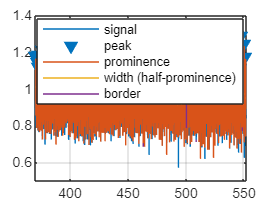

%%% RUN SECTION. ENSURE FOOTSTEPS ARE ALL EVENLY SPACED AND ALWAYS DETECTED.
%%% CHANGE 'MinPeakProminence' AND 'MinPeakDistance' AND RERUN SECTION UNTIL ^ IS TRUE.

% Plots the location of every heel strike using IMU data
findpeaks(C_trials.imu_T1(:,2),C_trials.imu_T1(:,4),'MinPeakProminence',0.2,'MinPeakDistance',0.3,'Annotate','extents')

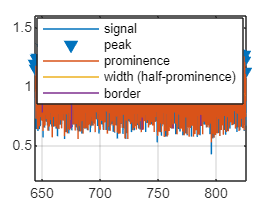

findpeaks(C_trials.imu_T2(:,2),C_trials.imu_T2(:,4),'MinPeakProminence',0.2,'MinPeakDistance',0.4,'Annotate','extents')

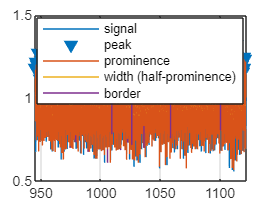

findpeaks(C_trials.imu_T3(:,2),C_trials.imu_T3(:,4),'MinPeakProminence',0.2,'MinPeakDistance',0.4,'Annotate','extents')

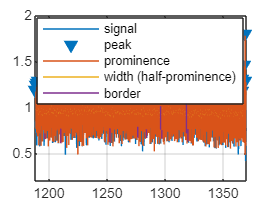

findpeaks(C_trials.imu_T4(:,2),C_trials.imu_T4(:,4),'MinPeakProminence',0.2,'MinPeakDistance',0.4,'Annotate','extents')


% Uses the same function as above to store heel strike locations in seconds in locs_TX
[~,locs_T1] = findpeaks(C_trials.imu_T1(:,2),C_trials.imu_T1(:,4),'MinPeakProminence',0.2,'MinPeakDistance',0.3,'Annotate','extents')

locs_T1 =   370.3140
  371.0180
  371.6400
  372.2920
  372.8940
  373.5780
  374.2100
  374.8020
  375.4760
  376.1180


[~,locs_T2] = findpeaks(C_trials.imu_T2(:,2),C_trials.imu_T2(:,4),'MinPeakProminence',0.2,'MinPeakDistance',0.4,'Annotate','extents')

locs_T2 =   644.4860
  645.0980
  645.7500
  646.3540
  646.9160
  647.5580
  648.1000
  648.7020
  649.3160
  649.9180


[~,locs_T3] = findpeaks(C_trials.imu_T3(:,2),C_trials.imu_T3(:,4),'MinPeakProminence',0.2,'MinPeakDistance',0.4,'Annotate','extents')

locs_T3 = 	1.0e+03 *

    0.9451
    0.9458
    0.9465
    0.9471
    0.9477
    0.9483
    0.9489
    0.9496
    0.9502
    0.9509


[~,locs_T4] = findpeaks(C_trials.imu_T4(:,2),C_trials.imu_T4(:,4),'MinPeakProminence',0.2,'MinPeakDistance',0.4,'Annotate','extents')

locs_T4 = 	1.0e+03 *

    1.1884
    1.1891
    1.1897
    1.1904
    1.1910
    1.1916
    1.1923
    1.1929
    1.1935
    1.1942


## Plotting averaged EMG data relevant to each foot strike 

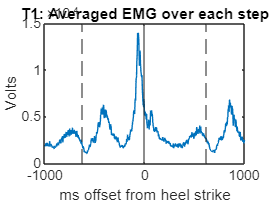

%%% RUN SECTION, THEN PICK ODD HEEL-STRIKES OR EVEN HEEL-STRIKES TO BE THE RIGHT LEG AND RERUN.
% Max EMG should occur just before the heel strike (solid line), or close to it  

odd_T1=1; %1 IF ODD, 0 IF EVEN
odd_T2=1; %1 IF ODD, 0 IF EVEN
odd_T3=1; %1 IF ODD, 0 IF EVEN
odd_T4=0; %1 IF ODD, 0 IF EVEN

StrideLengthSamples = 1000; %This is 2 seconds long, an overestimation of stride length in # of samples. Average stride is ~1.3 seconds.

%Calculating the average difference between heel strikes in ms, for plotting later
%(a more accurate calculation is used in Coherence_T_real.m)

AvgLocDifference_ms= mean(cat(1,diff(locs_T1(1:end)),diff(locs_T2(1:end)),diff(locs_T3(1:end)),diff(locs_T4(1:end)))) * 1000;

%By subtracting StartTime, we can assume every trial starts at t=0 seconds
StartTime_T1 = C_trials.eeg_T1(1,17); 
StartTime_T2 = C_trials.eeg_T2(1,17); 
StartTime_T3 = C_trials.eeg_T3(1,17); 
StartTime_T4 = C_trials.eeg_T4(1,17); 


%Averaging EMG data that is offset from a heel strike by the same time
for j=1:StrideLengthSamples 
    for i=4:(floor(length(locs_T1)/2)-4) %removing the start and end heel strikes, which are often incorrect 
        LocIndex = (locs_T1((i*2)+odd_T1)-StartTime_T1)*500+1; %This is the sample index where the heel-strike occurs
         f(i-3) = C_trials_p.emg_T1(round(LocIndex+(j-((StrideLengthSamples)/2))));
    end
    g(j)=mean(f);
end
%Plotting
domain=((-(StrideLengthSamples-2)/2):1:(StrideLengthSamples)/2);
plot(domain*2,g) % 500Hz means ~2ms per sample
title('T1: Averaged EMG over each step')
xlabel('ms offset from heel strike')
ylabel('Volts')
xline(AvgLocDifference_ms,'--')
xline(-AvgLocDifference_ms,'--')
xline(0);

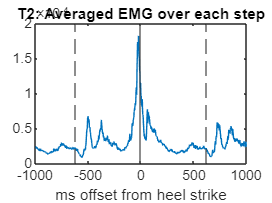

clear i j f g;


for j=1:StrideLengthSamples 
    for i=4:(floor(length(locs_T2)/2)-4)
        LocIndex = (locs_T2((i*2)+odd_T2)-StartTime_T2)*500+1; 
         f(i-3) = C_trials_p.emg_T2(round(LocIndex+(j-((StrideLengthSamples)/2))));
    end
    g(j)=mean(f);
end
domain=((-(StrideLengthSamples-2)/2):1:(StrideLengthSamples)/2);
plot(domain*2,g)
title('T2: Averaged EMG over each step')
xlabel('ms offset from heel strike')
xline(AvgLocDifference_ms,'--')
xline(-AvgLocDifference_ms,'--')
xline(0);

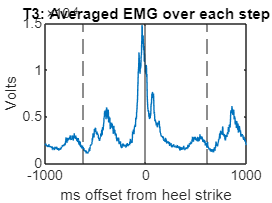

clear i j f g;


for j=1:StrideLengthSamples 
    for i=4:(floor(length(locs_T3)/2)-4)
        LocIndex = (locs_T3((i*2)+odd_T3)-StartTime_T3)*500+1; 
         f(i-3) = C_trials_p.emg_T3(round(LocIndex+(j-((StrideLengthSamples)/2))));
    end
    g(j)=mean(f);
end
domain=((-(StrideLengthSamples-2)/2):1:(StrideLengthSamples)/2);
plot(domain*2,g)
title('T3: Averaged EMG over each step')
xlabel('ms offset from heel strike')
ylabel('Volts')
xline(AvgLocDifference_ms,'--')
xline(-AvgLocDifference_ms,'--')
xline(0);

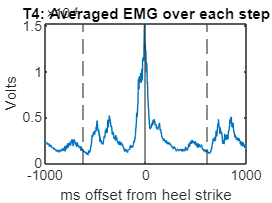

clear i j f g;


for j=1:StrideLengthSamples 
    for i=4:(floor(length(locs_T4)/2)-4)
        LocIndex = (locs_T4((i*2)+odd_T4)-StartTime_T4)*500+1; 
         f(i-3) = C_trials_p.emg_T4(round(LocIndex+(j-((StrideLengthSamples)/2))));
    end
    g(j)=mean(f);
end
domain=((-(StrideLengthSamples-2)/2):1:(StrideLengthSamples)/2);
plot(domain*2,g)
title('T4: Averaged EMG over each step')
xlabel('ms offset from heel strike')
ylabel('Volts')
xline(0);
xline(AvgLocDifference_ms,'--')
xline(-AvgLocDifference_ms,'--')

clear i j f g;

## Epoching the data

%Epochs the data into EMGepochs_TX and EEGepoch_TX matrices

%Initializing the matrices
EMGepochs_T1=zeros(floor(length(locs_T1)/2)-1,StrideLengthSamples);
EEGepochs_T1=zeros(floor(length(locs_T1)/2)-1,StrideLengthSamples,15); %15 is the number of EEG channels... Ensure this is true!

EMGepochs_T2=zeros(floor(length(locs_T2)/2)-1,StrideLengthSamples);
EEGepochs_T2=zeros(floor(length(locs_T2)/2)-1,StrideLengthSamples,15); 

EMGepochs_T3=zeros(floor(length(locs_T3)/2)-1,StrideLengthSamples);
EEGepochs_T3=zeros(floor(length(locs_T3)/2)-1,StrideLengthSamples,15); 

EMGepochs_T4=zeros(floor(length(locs_T4)/2)-1,StrideLengthSamples);
EEGepochs_T4=zeros(floor(length(locs_T4)/2)-1,StrideLengthSamples,15); 

%EMG Epochs
for i=4:(floor(length(locs_T1)/2)-4)
    LocIndex = round((locs_T1((i*2)+odd_T1)-StartTime_T1)*500+1); %This is the index where the heel-strike occurs
    EMGepochs_T1(i-3,:) = C_trials_p.emg_T1(LocIndex+(1-((StrideLengthSamples)/2)):LocIndex+(StrideLengthSamples-((StrideLengthSamples)/2)));
end
%EEG Epochs
for k=1:15
    for i=4:(floor(length(locs_T1)/2)-4)
        LocIndex = round((locs_T1((i*2)+odd_T1)-StartTime_T1)*500+1); %This is the index where the heel-strike occurs
        EEGepochs_T1(i-3,:,k) = C_trials_p.eeg_T1(LocIndex+(1-((StrideLengthSamples)/2)):LocIndex+(StrideLengthSamples-((StrideLengthSamples)/2)),k);
    end
end


%EMG Epochs
for i=4:(floor(length(locs_T2)/2)-4)
    LocIndex = round((locs_T2((i*2)+odd_T2)-StartTime_T2)*500+1); %This is the index where the heel-strike occurs
    EMGepochs_T2(i-3,:) = C_trials_p.emg_T2(LocIndex+(1-((StrideLengthSamples)/2)):LocIndex+(StrideLengthSamples-((StrideLengthSamples)/2)));
end
%EEG Epochs
for k=1:15
    for i=4:(floor(length(locs_T2)/2)-4)
        LocIndex = round((locs_T2((i*2)+odd_T2)-StartTime_T2)*500+1); %This is the index where the heel-strike occurs
        EEGepochs_T2(i-3,:,k) = C_trials_p.eeg_T2(LocIndex+(1-((StrideLengthSamples)/2)):LocIndex+(StrideLengthSamples-((StrideLengthSamples)/2)),k);
    end
end


%EMG Epochs
for i=4:(floor(length(locs_T3)/2)-4)
    LocIndex = round((locs_T3((i*2)+odd_T3)-StartTime_T3)*500+1); %This is the index where the heel-strike occurs
    EMGepochs_T3(i-3,:) = C_trials_p.emg_T2(LocIndex+(1-((StrideLengthSamples)/2)):LocIndex+(StrideLengthSamples-((StrideLengthSamples)/2)));
end
%EEG Epochs
for k=1:15
    for i=4:(floor(length(locs_T3)/2)-4)
        LocIndex = round((locs_T3((i*2)+odd_T3)-StartTime_T3)*500+1); %This is the index where the heel-strike occurs
        EEGepochs_T3(i-3,:,k) = C_trials_p.eeg_T3(LocIndex+(1-((StrideLengthSamples)/2)):LocIndex+(StrideLengthSamples-((StrideLengthSamples)/2)),k);
    end
end


%EMG Epochs
for i=4:(floor(length(locs_T4)/2)-4)
    LocIndex = round((locs_T4((i*2)+odd_T4)-StartTime_T4)*500+1); %This is the index where the heel-strike occurs
    EMGepochs_T4(i-3,:) = C_trials_p.emg_T4(LocIndex+(1-((StrideLengthSamples)/2)):LocIndex+(StrideLengthSamples-((StrideLengthSamples)/2)));
end
%EEG Epochs
for k=1:15
    for i=4:(floor(length(locs_T4)/2)-4)
        LocIndex = round((locs_T4((i*2)+odd_T4)-StartTime_T4)*500+1); %This is the index where the heel-strike occurs
        EEGepochs_T4(i-3,:,k) = C_trials_p.eeg_T4(LocIndex+(1-((StrideLengthSamples)/2)):LocIndex+(StrideLengthSamples-((StrideLengthSamples)/2)),k);
    end
end


## Troubleshooting: plots processed EMG data against footsteps 

% Optional, but helpful if your averaged EMG data looks incorrect.
plot(C_trials.eeg_T1(:,17),C_trials_p.emg_T1(:));
xline(locs_T1(1:2:end)); %odd ones, which are solid
xline(locs_T1(2:2:end),':'); %even ones, which are dotted
xlabel('Time (s)');ylabel('Volts (V)'); title('Processed EMG Plotted With Heel Strikes');

%Save your workspace as C_trials_p_epoched now! Then you don't have to repeat
%these steps when you close Matlab.

%%% INSERT FILE LOCATION (or just 'Save As' workspace)
save('C:\Users\Thomas\OneDrive - University of Cambridge\USRA\STUDY_DATA\Data\XX\C_trials_p_epoched.mat')